roblem 4.8 (**(*) Widma różnych sygnałów, czyli góry i doliny). Zdyskretyzuj czas (N=2000; fpr=2000; dt=1/fpr; t=dt*(0:N-1); oraz wygeneruj wszystkie sygnały zdefiniowane w tabeli 4.1. Oblicz widmo DFT każdego z nich za pomocą funkcji Matlaba fft(), narysuj je w skali liniowej i decybelowej oraz porównaj jego kształt z wzorem podanym w tabeli. Jeśli “ręcznie" obliczysz widma DtFT, to otrzymasz dodatkowy punkt ().

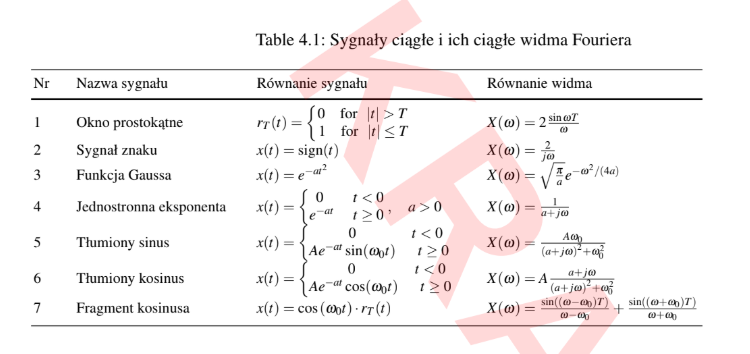

N = 2000;
fpr = 2000;
dt = 1/fpr;   % okres próbkowania trwa 0,0005s
% t = dt*(0:N-1);
t = -N/2:N/2 -dt;

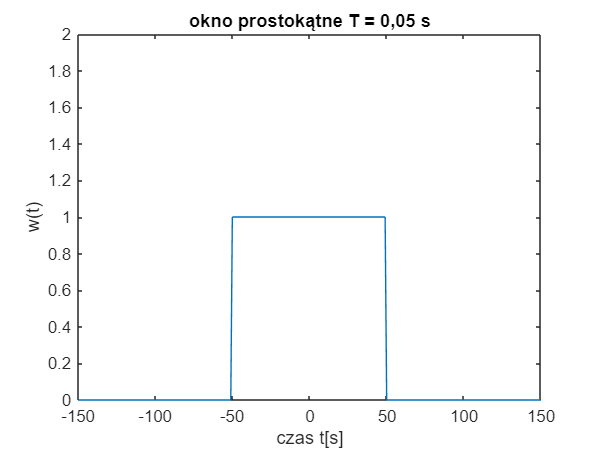

% 1. Okno prostokątne
T = 100;   % 100 próbek, okno trwa 0,05s
tau = 0.05;
x1 = [zeros(1,950) ones(1,T) zeros(1,950)];
plot(t,x1); ylim([0 2]); xlim([-150 150]);
xlabel('czas t[s]'); ylabel('w(t)'); title('okno prostokątne T = 0,05 s');

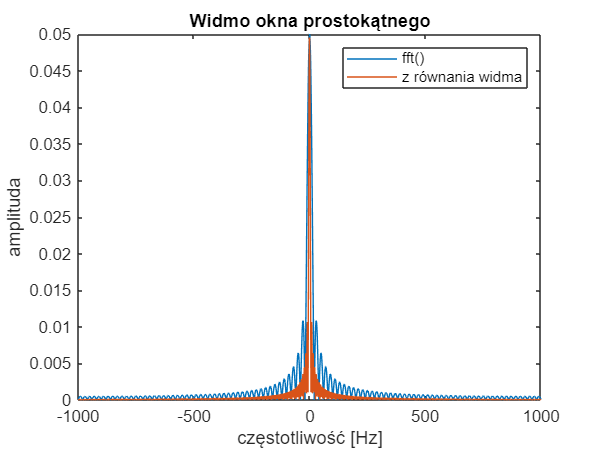

% Widmo okna prostokątnego
x1_w = fft(x1,2000) / N;
f = linspace(-fpr/2, fpr/2, 2000);

% skala liniowa
plot(f,fftshift(abs(x1_w))); hold on;
title('Widmo okna prostokątnego');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');

ref = tau*sinc(pi.*f.*tau);
plot(f,abs(ref)); legend('fft()','z równania widma'); hold off;

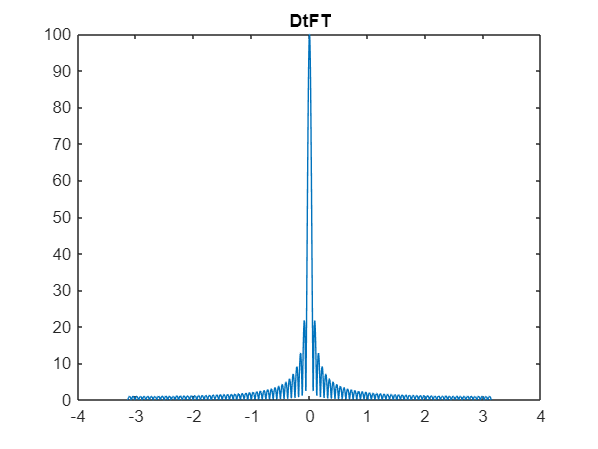


% DtFT
omega = 2 * pi * f / fpr;
for k = 1:length(omega)
    X1_dtft(k) = sum(x1 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X1_dtft));
title('DtFT');

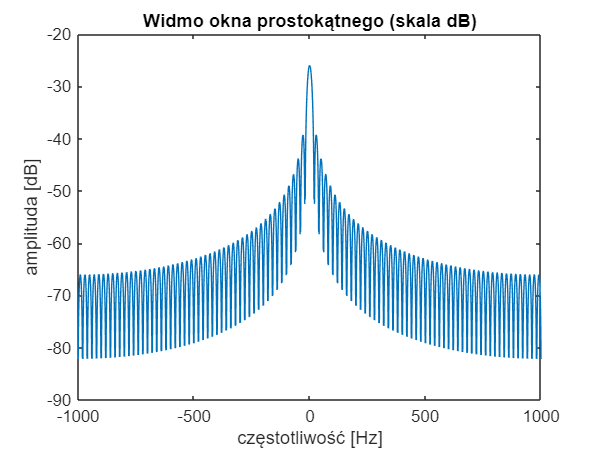


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(x1_w))));
title('Widmo okna prostokątnego (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');

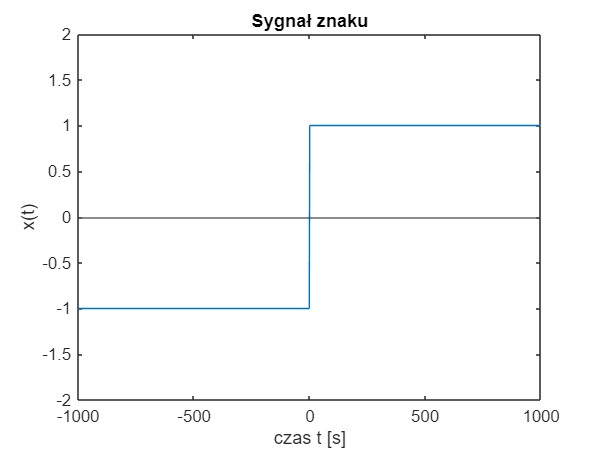

% sygnał znaku
t2 = -N/2:N/2 -dt;
x2 = sign(t2);
plot(t2,x2); title('Sygnał znaku');
xlabel('czas t [s]'); ylabel('x(t)');
ylim([-2 2]); yline(0);

disp(x2(1001));

     0



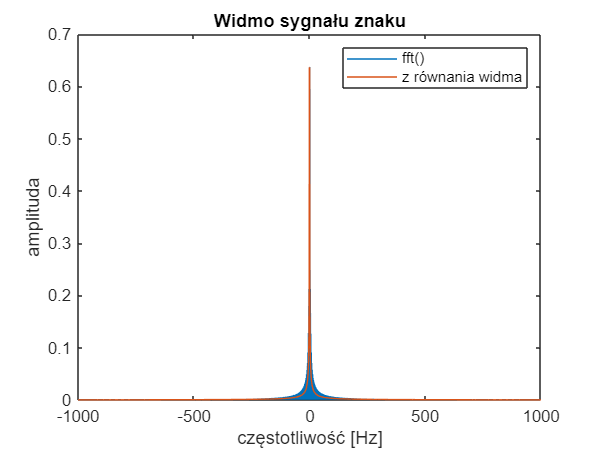


% widmo sign
X2 = fft(x2) / N;
% skala liniowa
plot(f,fftshift(abs(X2))); hold on;
title('Widmo sygnału znaku');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');

ref2 = 1 ./ (j*pi*f);
plot(f, abs(ref2)); legend('fft()','z równania widma'); hold off;

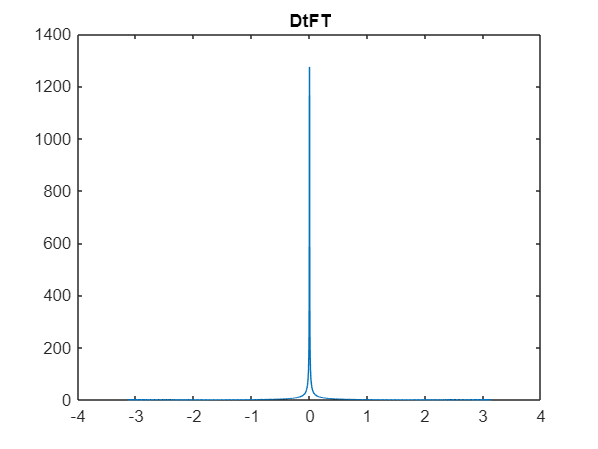


% DtFT
for k = 1:length(omega)
    X2_dtft(k) = sum(x2 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X2_dtft));
title('DtFT');

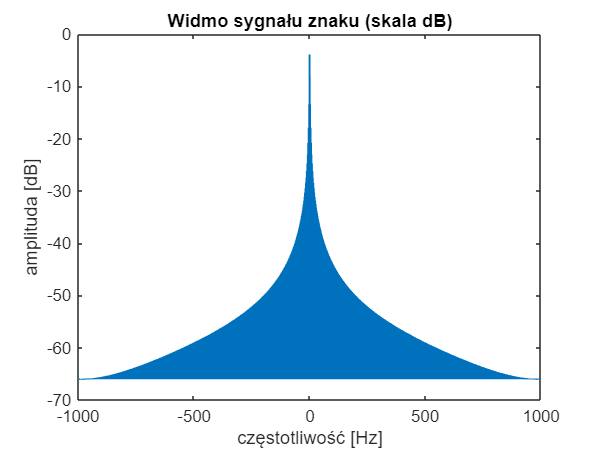


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(X2))));
title('Widmo sygnału znaku (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');

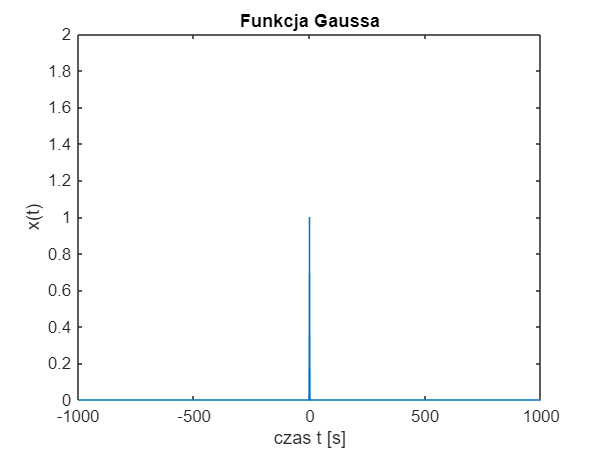

% Funkcja Gaussa
a = 1;
% t3 = -N/2:1/8:N/2 -dt; % zeby byla wyzsza rozdzielczosc
x3 = exp(-a * t.^2);
przedzial = 990:1010;
% plot(t(przedzial),x3(przedzial)); title('Funkcja Gaussa');
plot(t,x3); title('Funkcja Gaussa');
xlabel('czas t [s]'); ylabel('x(t)');
ylim([0 2]);

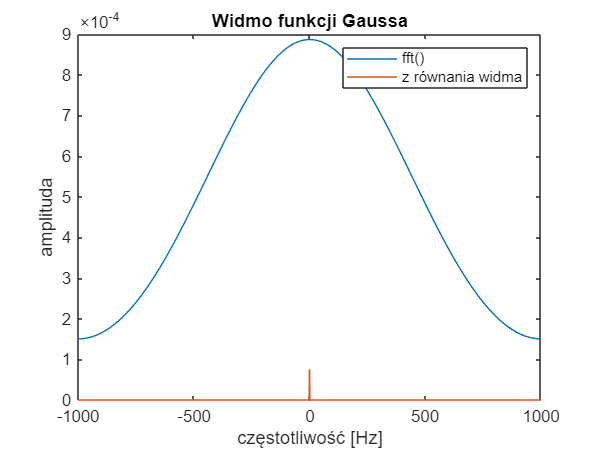


% widmo funkcji Gaussa
X3 = fft(x3) / N;
% skala liniowa
plot(f,fftshift(abs(X3))); hold on;
title('Widmo funkcji Gaussa');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');

ref3 = dt * sqrt(pi/a)*exp(-(pi^2*f.^2)/a);
plot(f, abs(ref3)); legend('fft()','z równania widma'); hold off;

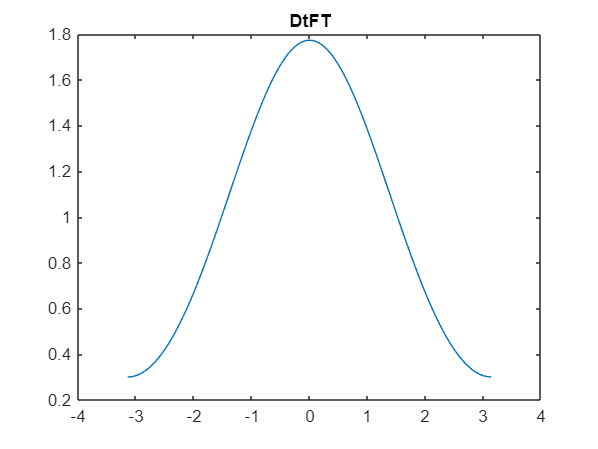


% DtFT
for k = 1:length(omega)
    X3_dtft(k) = sum(x3 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X3_dtft));
title('DtFT');

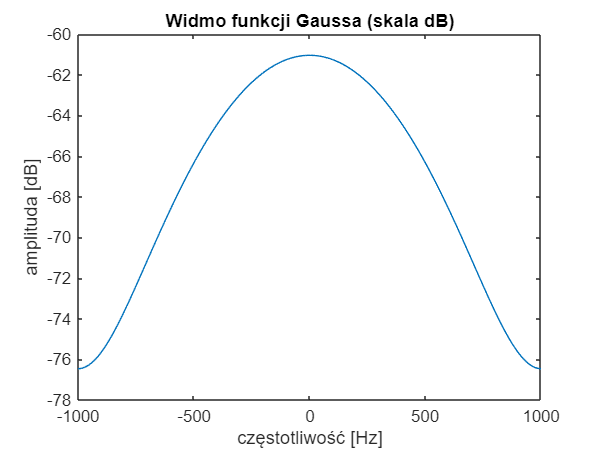


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(X3))));
title('Widmo funkcji Gaussa (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');

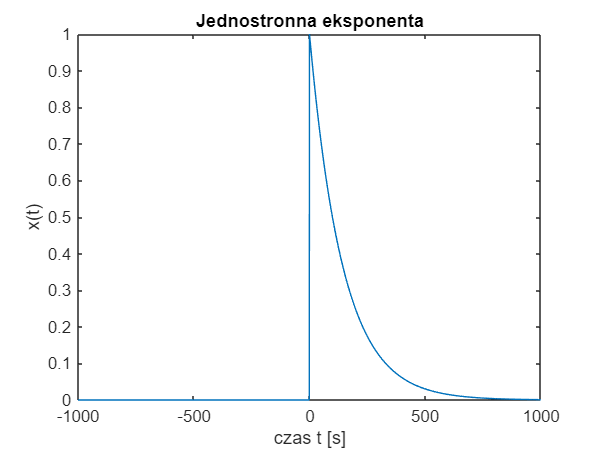

% Jednostronna eksponenta
t4 = t(1001:end);
a = 0.007;
prawa = exp(-a*t4);
x4 = [zeros(1,1000) prawa];
plot(t, x4); title('Jednostronna eksponenta');
xlabel('czas t [s]'); ylabel('x(t)');

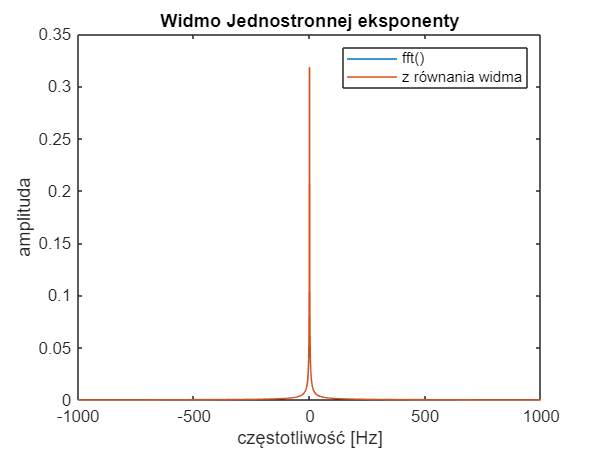


% widmo Jednostronnej eksponenty
X4 = fft(x4) / N;
% skala liniowa
plot(f,fftshift(abs(X4))); hold on;
title('Widmo Jednostronnej eksponenty');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');

ref4 = 1 ./ (a + j*2*pi*f);
plot(f,abs(ref4)); legend('fft()','z równania widma'); hold off;

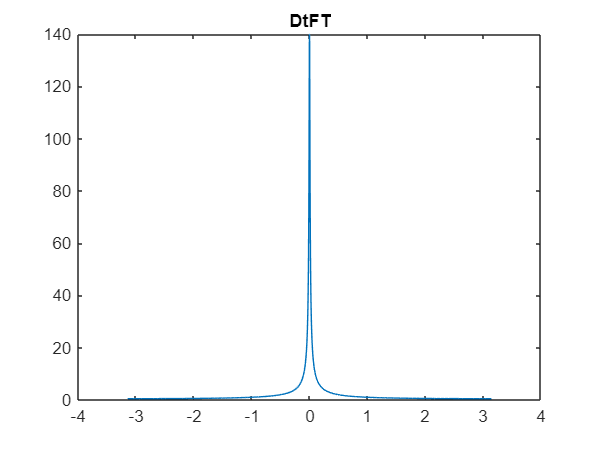


% DtFT
for k = 1:length(omega)
    X4_dtft(k) = sum(x4 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X4_dtft));
title('DtFT');

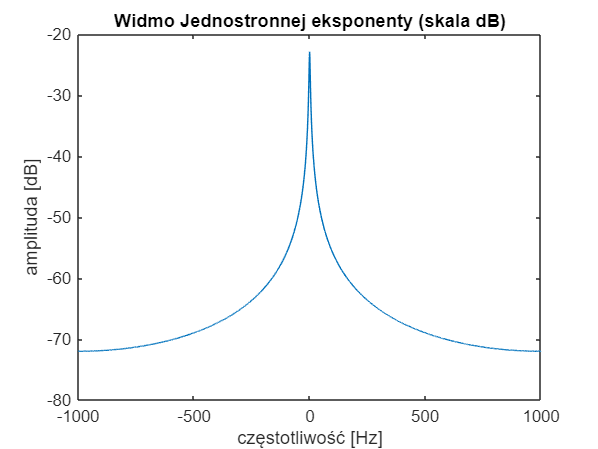


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(X4))));
title('Widmo Jednostronnej eksponenty (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');

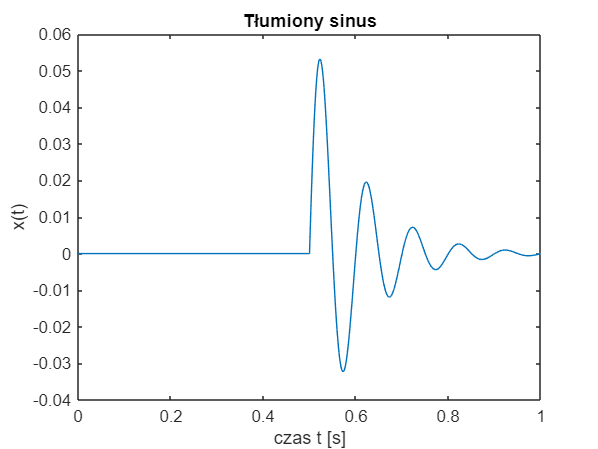


% Tłumiony sinus
a = 10;
A = 10;
t5 = 0:1/fpr:1 - 1/fpr;
f5 = 10;
x5 = A*exp(-a*t5).*sin(2*pi*f5*t5);
x5(t < 0) = 0;
plot(t5,x5); title('Tłumiony sinus');
xlabel('czas t [s]'); ylabel('x(t)');

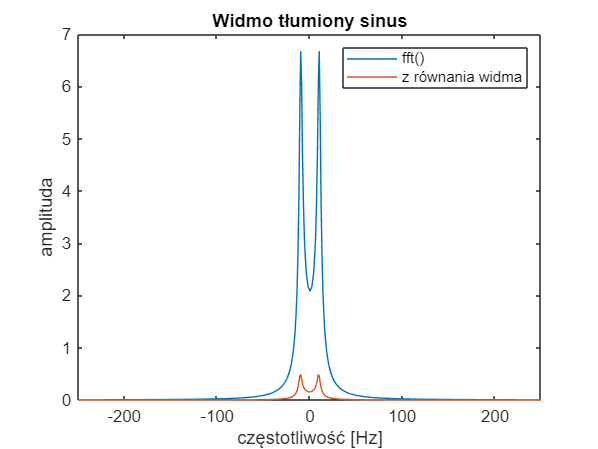


% widmo tłumiony sinus
X5 = fft(x5);
% skala liniowa
X5_shifted = fftshift(abs(X5));
plot(f,X5_shifted); hold on;
title('Widmo tłumiony sinus');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');
xlim([-250 250]);
% widac "dzwony" wokol +- 10 Hz

w0 = 2*pi*f5;
ref5 = (A * w0) ./ ((a + j*2*pi*f).^2 + w0^2);
plot(f, abs(ref5)); legend('fft()','z równania widma'); hold off;

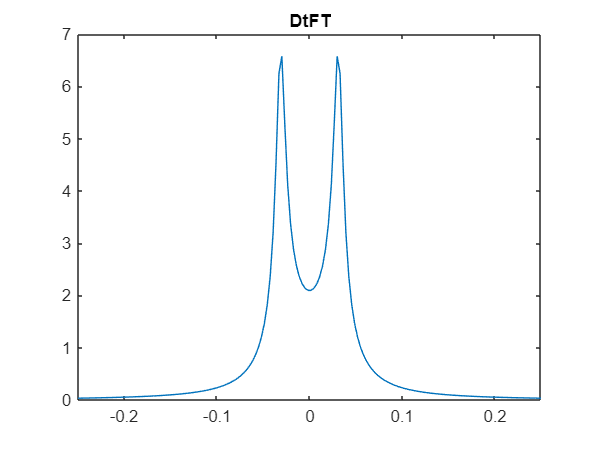


% DtFT
for k = 1:length(omega)
    X5_dtft(k) = sum(x5 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X5_dtft));
title('DtFT');
xlim([-0.25 0.250]);

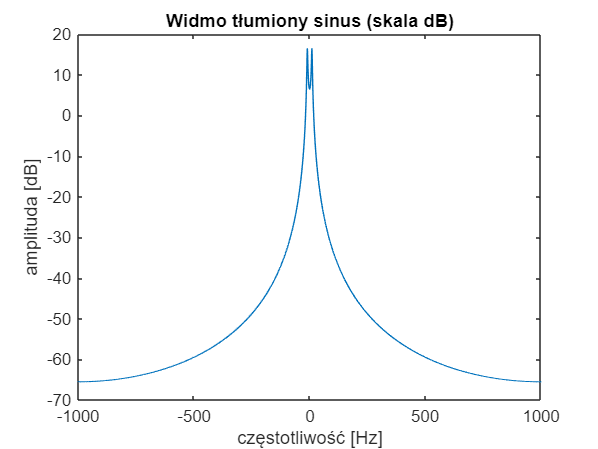


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(X5))));
title('Widmo tłumiony sinus (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');

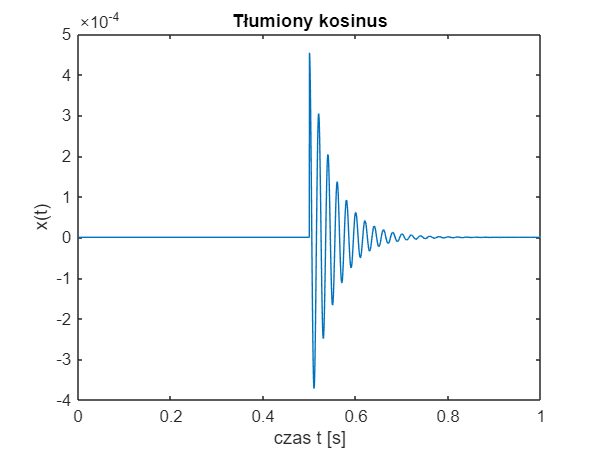

% Tłumiony kosinus
a = 20;
A = 10;
t6 = 0:1/fpr:1 - 1/fpr;
f6 = 50;
x6 = A*exp(-a*t6).*cos(2*pi*f6*t6);
x6(t < 0) = 0;
plot(t6,x6); title('Tłumiony kosinus');
xlabel('czas t [s]'); ylabel('x(t)');

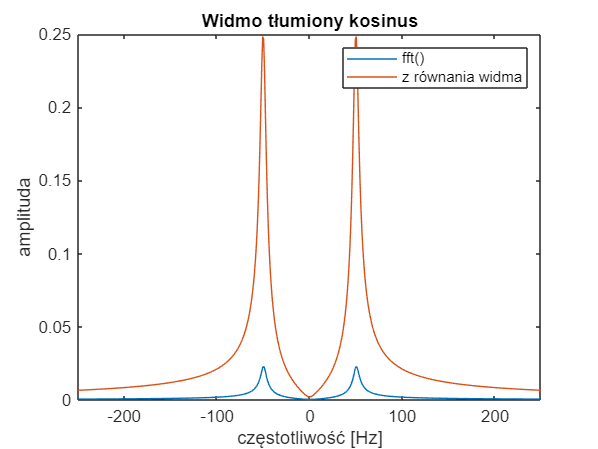


% widmo tłumiony ksinus
X6 = fft(x6);
% skala liniowa
X6_shifted = fftshift(abs(X6));
plot(f,X6_shifted); hold on;
title('Widmo tłumiony kosinus');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');
xlim([-250 250]);
% widac "dzwony" wokol +- 10 Hz

w0 = 2*pi*f6;
ref6 = A * (a + j*2*pi*f) ./ ((a + j*2*pi*f).^2 + w0^2);
plot(f, abs(ref6)); legend('fft()','z równania widma'); hold off;

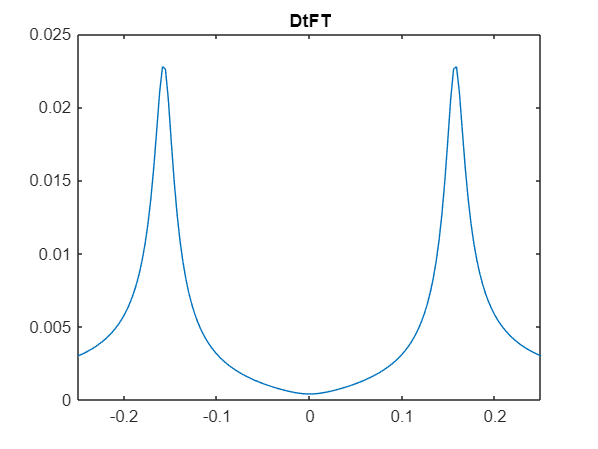


% DtFT
for k = 1:length(omega)
    X6_dtft(k) = sum(x6 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X6_dtft));
title('DtFT');
xlim([-0.25 0.250]);

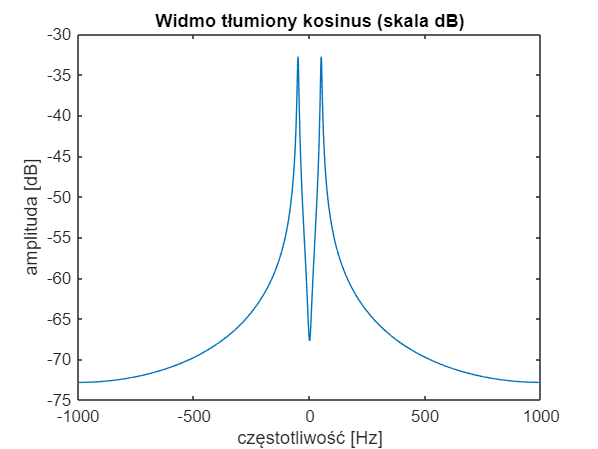


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(X6))));
title('Widmo tłumiony kosinus (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');

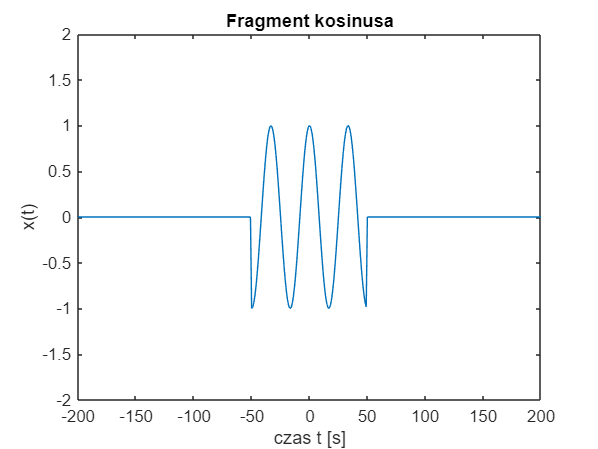

% Fragment kosinusa
t7 = 0:1/fpr:1 - 1/fpr;
f7 = 60;
w0 = 2*pi*f7;
x7 = cos(w0*t7) .* x1;
plot(t,x7); title('Fragment kosinusa');
xlabel('czas t [s]'); ylabel('x(t)');
xlim([-200 200]); ylim([-2 2]);

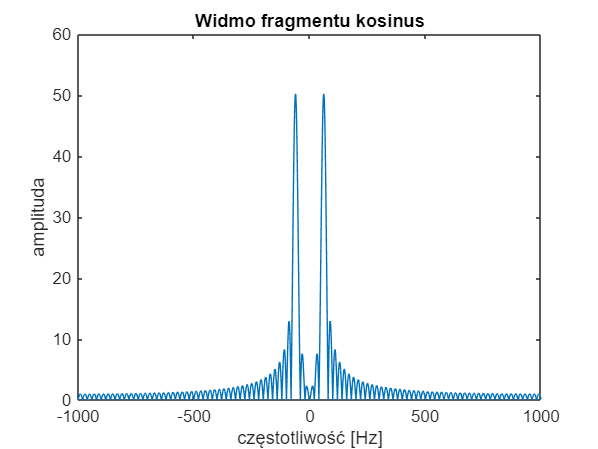


% widmo fragmentu kosinusa
X7 = fft(x7);
plot(f,fftshift(abs(X7)));
title('Widmo fragmentu kosinus');
xlabel('częstotliwość [Hz]');
ylabel('amplituda');

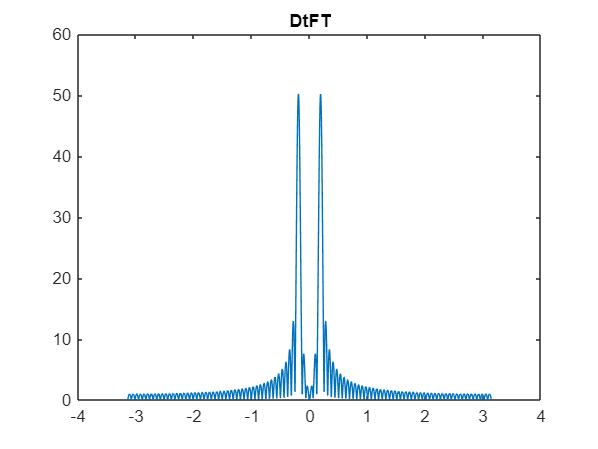


% DtFT
for k = 1:length(omega)
    X7_dtft(k) = sum(x7 .* exp(-j*omega(k) * (0:N-1)));
end
plot(omega, abs(X7_dtft));
title('DtFT');

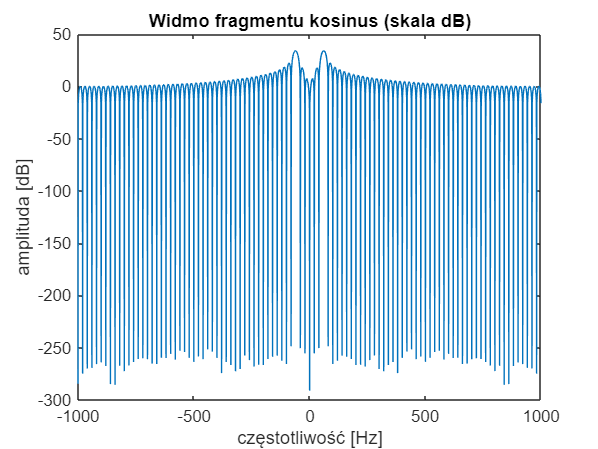


% skala logarytmiczna
plot(f,20*log10(fftshift(abs(X7))));
title('Widmo fragmentu kosinus (skala dB)');
xlabel('częstotliwość [Hz]');
ylabel('amplituda [dB]');